%该文件用来绘制影长随纬度的变化图

n=n_days(2015,10,22);%根据自定义函数求得n
lait=-30:0.1:51;%定义纬度
t=12;%取北京时间12点作为参考量
st_t=t-8+(116+23/60+29/3600)/15;%根据自定义函数转化为当地标准时间
H=((15*(st_t-12))/180)*2*pi;%H为太阳时角
delte=abs((23.45*sin(2*pi*(284+n)/365))/180)*2*pi;%delte为太阳赤纬
L=3;%表示直杆长度

l=zeros(1,size(lait,2));%用来存储所求的所有影长
for i=1:size(lait,2) 
    phi=(lait(i)/180)*2*pi;%定义纬度
    alpha=asin(sin(delte)*sin(phi)+cos(delte)*cos(phi)*cos(H));%alpha为太阳光线的入射角度
    l(1,i)=abs(L/tan(alpha));%l表示此时影长
end
[lmax,indax]=max(l)

lmax =   30.659055836496826


indax =      1


[lmin,indin]=min(l)

lmin =    0.346045949665942


indin =    423


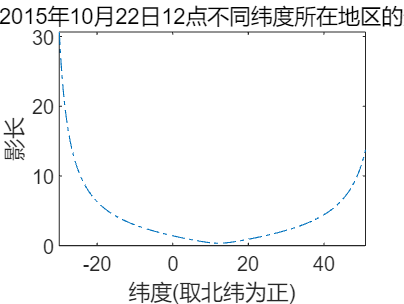


figure(1)
plot(lait,l,'-.');
title('北京时间2015年10月22日12点不同纬度所在地区的影长变化图');
xlabel('纬度(取北纬为正)');
ylabel('影长');
xlim([-30,51]);